clear variables; close all; clc;

## Assignment 2 

Another friend of Peter’s studies unicellular microalgae (symbiodinium necroappetens) which also have a RING1 protein, but it is much longer than the human version.  The accession number of this protein is CAE7901930. How close is the algae version to the human protein?  Explain your results.

## Load Sequences

Load human and algae sequences and take them length.

human = getgenpept('CAA78389', SequenceOnly=true);
seqdisp(human)

ans = 7×70 char array
    '  1  MDGTEIAVSP RSLHSELMCP ICLDMLKNTM TTKECLHRFC SDCIVTALRS GNKECPTCRK'
    ' 61  KLVSKRSLRP DPNFDALISK IYPSREEYEA HQDRVLIRLS RLHNQQALSS SIEEGLRMQA'
    '121  MHRAQRVRRP IPGSDQTTTM SGGEGEPGEG EGDGEDVSSD SAPDSAPGPA PKRPRGGGAG'
    '181  GSSVGTGGGG TGGVGGGAGS EDSGDRGGTL GGGTLGPPSP PGAPSPPEPG GEIELVFRPH'
    '241  PLLVEKGEYC QTRYVKTTGN ATVDHLSKYL ALRIALERRQ QQEAGEPGGP GGGASDTGGP'
    '301  DGCGGEGGGA GGGDGPEEPA LPSLEGVSEK QYTIYIAPGG GAFTTLNGSL TLELVNEKFW'
    '361  KVSRPLELCY APTKDPK                                               '


human_length = length(human);

algae = getgenpept('CAE7901930', SequenceOnly=true);
seqdisp(algae)

ans = 21×71 char array
    '   1  MASFAPLRRS RGLALLVLSL PLCCFVSAWG TARGRRVEYQ ARHAAPEPAE PELASPAWEE'
    '  61  SAQVVLEIVE DSTKEDALDW LQAGYAWTAK SRRFWRKLRS PMPPEPEAVR RTARWLQDKG'
    ' 121  LAQKAWVRRF PEVLGLSVED LEEGRSTAPS YLKSEDTYNK AIKSNPTLLG KNYDCLQEHE'
    ' 181  SCQGRCSRCW NTTDAEQSEQ YTLCGCLGFL GGLSILENIG PLKLRAGSSS GTVSGLSSIS'
    ' 241  GSSYQAAMKH ALLLLALPAH ATQISTEDPA LLSDEQASLR EEDEWRPSAQ ATFPRPSYGN'
    ' 301  GWSPWSGNPG SLPGGPAAHL PYQAVPRVPA PPPAGTFPKV AVSSAASGAG PNNLKEAEAE'
    ' 361  TKKFFEIEEM VAKETGLPLN SSEAAQKEEE EKAEAKEVEE EEEEERFDAL YAGIALVILL'
    ' 421  AAGGTFYFHR WSQDKPKPGE ALGAAAPSSP EADPKAPGPA EAEAKAATGR MKRKLLQLQV'
    ' 481  LILLSPLSEG PLSCQWGERW PLPDPSPSEG AMGKKRKAEF EPPPVNLDAL PPLEEGILRF'
    ' 541  EFTLEEKGAL GVRFSGGSPP MILSVAPDSF ASKKGIPVNY EVHAINGLAL VQQNQQRVMH'
    ' 601  FLKSRPVVLD VRPLGWKPPE KMKELKRRQQ QEEAEQKAKM AVEKKRREQD GWKVEMHSEE'
    ' 661  IQQFNADVRQ VFSSVFSACT WLSKPNERSP QLVPQKPLPL GQNQLRVCEE LERLGLLKAS'
    ' 721  PLPSPFVVAF HELLSSPVGG ECSCGAMG

algae_length = length(algae);

## Display sequence alignment plot

Display sequence alignment plot to inspect wether there are identifiable alignment areas.

seqdotplot(human, algae);

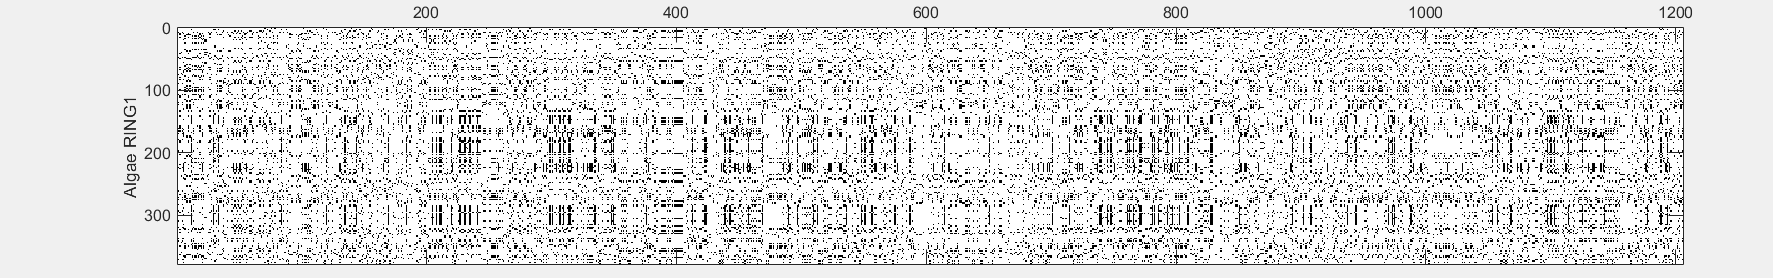

title("Sequences alignment dotplot");
xlabel("Human RING1"); ylabel("Algae RING1");

From the alignment graph we can see very few diagonal lines, and this may be sign of a poor score in global alignment, hence we might decide for local alignment and maybe improve by changing the scoring matrix using BLOSUM30, which will evaluate the alignment score in a smaller algorithmic window frame.

%[score50,aligment50] = swalign(human,algae)
[score30,alignment30] = swalign(human,algae,'scoringmatrix', 'blosum30')

score30 = 53.2000

alignment30 = 3×306 char array
    'MDGTE-IAVSPRSLHSEL--MCPICL-DMLKNTMTT-KECLHRFCSDCIVTALRSGNKECPTCRKKLVSKRSLRPDPNFDALISKIYPSREEYEAHQDRVLIRLSRLHNQQALSSSIEEGLRMQAMHRAQRVRRPIPGSDQTTTMSGGEGEPGEGEGDGEDVSSDSAP-DSAPGPAPKRPRGGGAGGSSVGTGGGGTGGVGGGAGSEDSGDRGGTLGGGTLGPPSPPGAP-SPPEPGGEIELVFRPHPLLVEKGEYCQT-RYVKT-TGNA-TVDHLSKYLALRIALERRQQQEAGEPGGPGGGASD'
    ':|::: ::|:: :| :::  :| :|| |  :::::| : | | ||: ||   ||::|  ||:|| :|::: :  ::     : ::|:  |:: |    |:   | ||::  ||: |  ||: ::   ||  | |:::|:  : ::   ::|: :   | :|::  : |   :  : :: |    :  |:      :: :: : ||    |: : |    : | :  |: | :::||:  :  :| | :   |:||  :: :: :| :| :  ::  ::  | | | |  :::    ||::: :::|'
    'RDALPRVVVTKEDLLDATNSKCSVCLEDYRPGVRATRMLCGHLFCTGCIREWLREANT-CPVCRYELATDCEDFESGRRTRMSGRIVRLRAA-ELRMLRI-SELRRLMD--ALGVSG-EGC-LE---RADLV-RHLEGAPDVEVAPELSAEK-KFRYDLQDLEQLDLPLLRNLMERHRVPFDLEEDLSEDDERRVALRSF-ADAG-WMRGA-SKTPPKPSEGAKQMPARPENTTEPAQTTTAAFVPSTDAGESGESGESEMRSETPSGESCEAKSRAAGKAARPA-EPPPARRRPRPGAKAEAKAD'


## Generate permutations

Now we assess if the alignment data are significant by generating permutations of the algae sequence and evaluating alignments with the original human protein sequence

a) Firstly with **randperm**.  We permute the data for the one of the sequences many times and generate the alignment scores of these permuted sequences to the original for the other.

PERMUTATIONS = 1000;
scores1 = double.empty;
for i = 1:PERMUTATIONS
    rand = randperm(algae_length);
    perm = algae(rand);
    scores1(i) = swalign(human,perm,'scoringmatrix','blosum30');
end

b) Secondly, we generate random sequences with the same features as our original sequence. We use **aacount** to count the number of times each amino acid occurs in the shorter sequence, then we use **randseq **with the **FROMSTRUCTURE** option to generate sequences based on that distribution. 

scores2 = double.empty;
aa_algae = aacount(algae);

for i=1:PERMUTATIONS
    rand = randseq(algae_length, 'fromstructure',aa_algae);
    scores2(i) = swalign(human, rand,'showscore',false);
end


## Plot results

As the documentation suggests: alignments scores randomly generated can be approximated by the type 1 extreme value distribution. Hence we can use the evfit function to estimate the parameters of this distribution

Now we plot an histogram showing scores distribution for a), marking in red the distribution shape and the real score initially achieved with alignment.

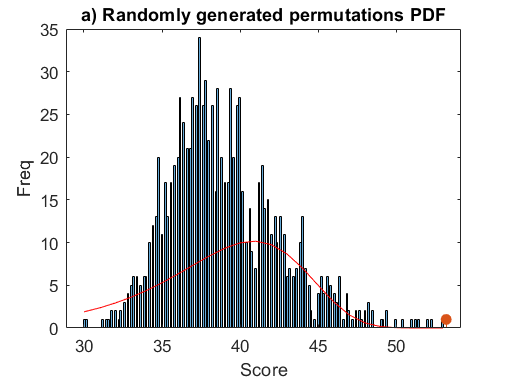

figure
b = ceil(PERMUTATIONS/5);                           % # buckets
h1 = histogram(scores1,b);                          % plot histogram 1
hold on;            
stem(score30,1,'filled')                            % plot initial score (original)
title('a) Randomly generated permutations PDF');
xlabel('Score'); ylabel('Freq');
ph1 = evfit(scores1);                               % estimate parameters type 1 dist.
x = min(scores1):max([scores1 score30]);            % x range 
y = evpdf(x,ph1(1),ph1(2));                         % generate PDF with given parameters
plot(x,PERMUTATIONS* h1.BinWidth*y,'r');            % plot PDF with scaled size
hold off;

Repeat procedure for b) experiment

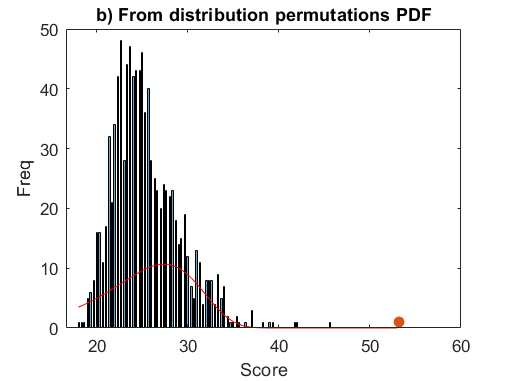

figure
h2 = histogram(scores2,b);                          % plot histogram 2
hold on;
stem(score30,1,'filled')                            % plot initial score (original)
title('b) From distribution permutations PDF');
xlabel('Score'); ylabel('Freq');
ph2 = evfit(scores2);                               % estimate parameters type 1 dist.
x = min(scores2):max([scores2 score30]);            % x range
y = evpdf(x,ph2(1),ph2(2));                         % generate PDF with given parameters
plot(x,PERMUTATIONS* h2.BinWidth*y,'r');            % plot PDF with scaled size
hold off;

## Conclusions

As we can see from the plots, the data we get from these experiments are statistically significant given that the plotted score achieved with original evaluation rely on the type 1 PDF obtained by estimating maximum likelihood parameters (mu, sigma) given the set of scores as data.

Hence we can assume that there is statistical evidence of a local alignment between human and algae RING1 protein.